## Receiver Modelling

#### Approach #1

 //Automatic Gain Control

 //Matched Filter to Tx (Raised Cosine)

 //Frequency compensation

 //Symbol Synchronisation

 //Carrier Synchronisation

#### Approach #2

//phase and polarisation detection

//ADC

//De-skew and orthonormalisation

//Static Channel Equalisation

//Dynamic Channel Equalisation

//Interpolation and timing recovery

//Frequency Estimation

//Carrier Phase Estimation

//Symbol Estimation and Decoding

#### Approach #3

//I/Q imbalance correction <-- appears in analog homodyne systems (maybe unnessesary)

//Chromatic Dispersion compensation

//Clock Phase Recovery

//Adaptive TDE MIMO-CMA

//Upsampling/Downsampling 

(up done by kron, alt. sine-windowed sinc function), (down done by intdump, alt. Hamming windowed sinc of size three)

//Carrier Frequency Recovery

//Carrier Phase Recovery

## Definitions of constants/variables

%Resetting the rng seed
rng("default");
rng(1960);

symbol_num = 32*1024; 

%%Sets of signals to be manipulated in different ways
%These sets are also the SNR Values
sets = linspace(1,50,30);
sets_num = length(sets);

symbol_rate = 100e9; % GBaud  (This needs sampling of 200e9 Samples/s)
time_step = 1/symbol_rate; %seconds
linewidth = 100e3; %Hz
variance=2*pi*linewidth*time_step;


symbols = randi([0 3],1,symbol_num);

%%% Sampling notes: To remove aliasing effect from ADC we need 2x
%%% oversampling at 2/T. Meaning at symbol rate of 25GBd -> sampling rate
%%% of 50GS/s -> for QPSK, a rate of 100 Gb/s

## QPSK Modulation

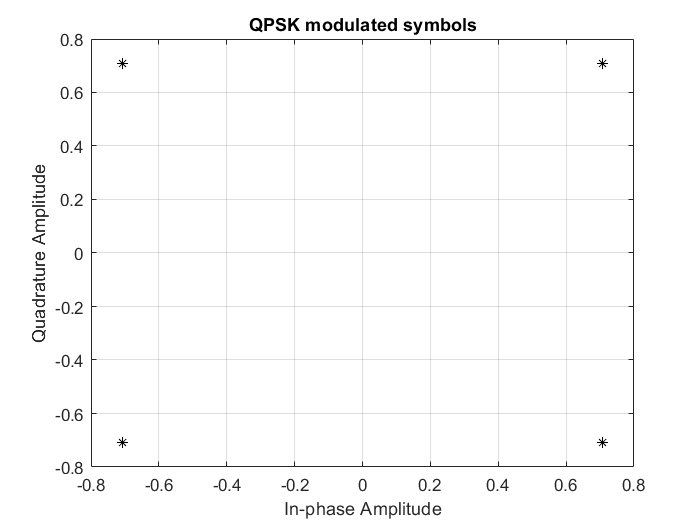

modulated_symbols = pskmod(symbols,4,pi/4,'gray');
%demod_symbols = pskdemod(modulated_symbols,4,0,'gray');

figure
plot(modulated_symbols,'*','MarkerEdgeColor','black','MarkerFaceColor',"black");
title("QPSK modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
grid on;

## D/A and A/D Conversion

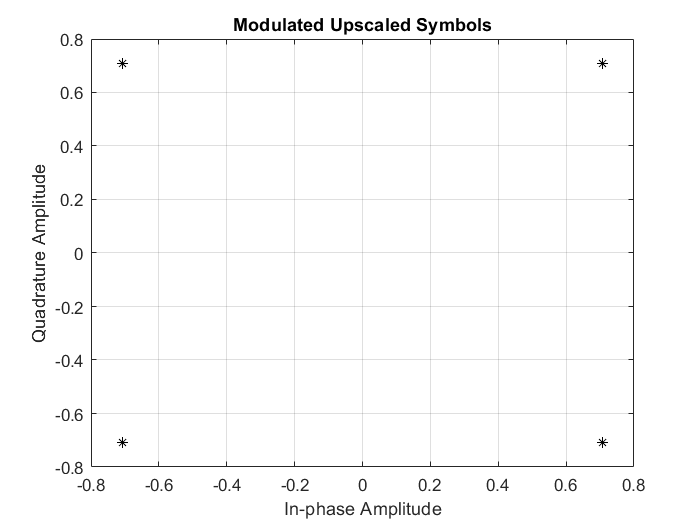

%{
symbol_rate = 100e9; 
time_step = 1/symbol_rate; 
linewidth = 100e3;
variance=2*pi*linewidth*time_step;}
%}

%TODO create symbols of a known sequence for easier debugging
%Look into these (for analog conversion):
%need to downsample
%with integrate and dump 

upscaling = 8;
kron_symbols = kron(symbols,ones(1,upscaling));

mod_kron_symbols = pskmod(kron_symbols,4,pi/4,'gray'); %QPSK gray modulation
plot(mod_kron_symbols,'*','MarkerEdgeColor','black');
title("Modulated Upscaled Symbols")
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
grid on;
hold off;


downscaled_mod_symbols = intdump(mod_kron_symbols,upscaling);

demoded_symbols = pskdemod(downscaled_mod_symbols,4,pi/4,'gray');

## AWGN and Phase Noise

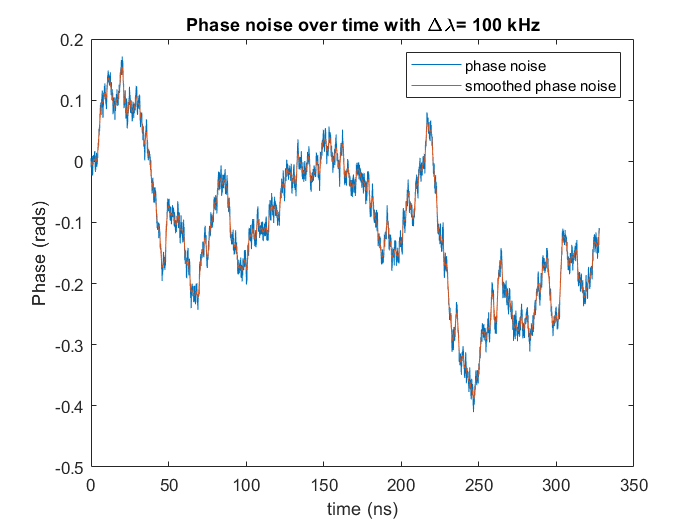

%%%Phase noise modeled as random walk%%%
% The cummulative sum of the standard deviations of each symbol's 
% phase as they are passed through the channel
rng(1960);

phase_noise = randn(1,symbol_num);

example_random_walk_phase_noise = cumsum(sqrt(variance).*phase_noise);

variances = (variance .* sets)';

phase_noise_sets = exp(1j*cumsum(sqrt(variances).* phase_noise));

t = (1:symbol_num)*time_step*1e9; %in nanoseconds


figure
plot(t,example_random_walk_phase_noise,t,filtfilt(ones(100,1)/100,1,example_random_walk_phase_noise));
title('Phase noise over time with \Delta\lambda= 100 kHz');
xlabel("time (ns)");
ylabel("Phase (rads)");
legend("phase noise","smoothed phase noise");

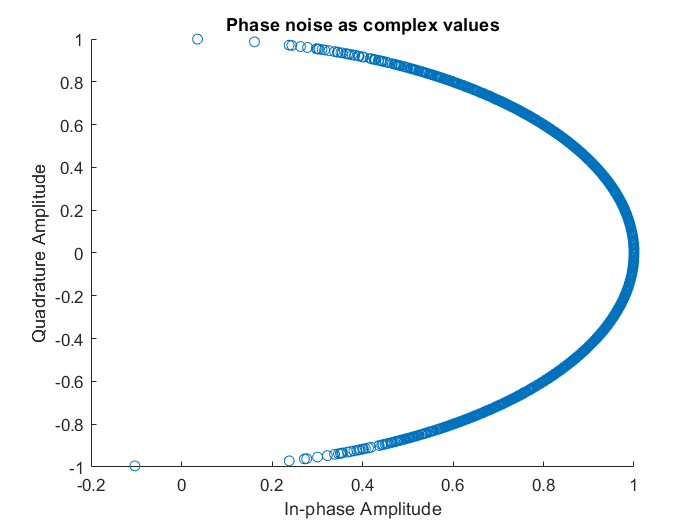



figure
scatter(real(phase_noise_sets(sets_num,:)),imag(phase_noise_sets(sets_num,:)));
title('Phase noise as complex values');
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");

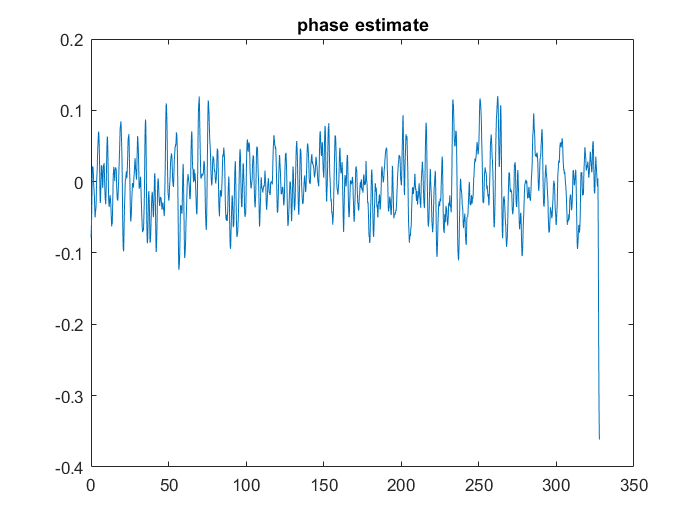


%%% Both phase and amplitude modified:
%phase_noise_sets = cumsum(sqrt(variances).*exp(1j*phase_noise));

%noisy_modulated_symbols = modulated_symbols .* phase_noise_sets;
%noisy_demod_symbols = pskdemod(noisy_modulated_symbols,4,0,"gray");

snr_values = sets;

awgn_symbol_sets = zeros(1,symbol_num);

for i=1:sets_num
    awgn_symbol_sets(i,:) = awgn(modulated_symbols,snr_values(i));
end

%%Add the largest phase noise and plot on the same graph for comparison
phase_awgn_symbol_sets = awgn_symbol_sets .* phase_noise_sets(sets_num,:);

%%Simple phase noise detection
%one-line approach
%phase_estimate = angle(-filtfilt(ones(100,1)/100,1,(phase_awgn_symbol_sets(30,:) .^ 4)))/4;

low_pass_filtered_noise = zeros(sets_num,symbol_num);

raised_phase_sets = phase_awgn_symbol_sets .^4;

for i=1:sets_num
low_pass_filtered_noise(i,:) = filtfilt(ones(100,1)/100,1,raised_phase_sets(i,:));
end

phase_estimate = angle(-low_pass_filtered_noise)/4;

plot(t,phase_estimate(sets_num,:));
title('phase estimate');

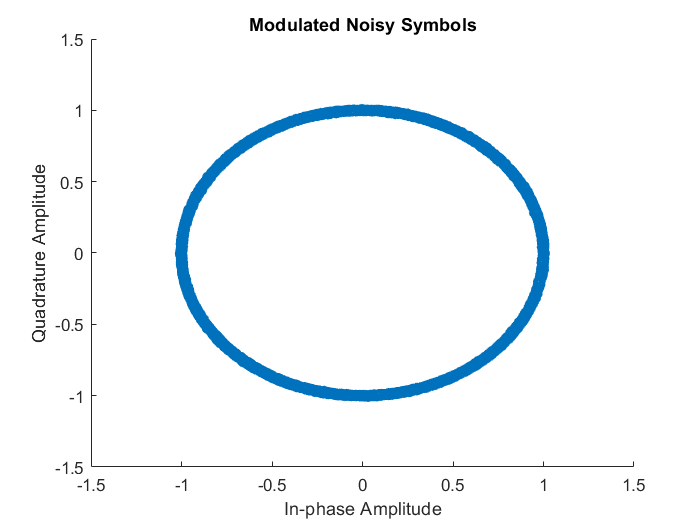


figure
scatter(real(phase_awgn_symbol_sets(sets_num,:)),imag(phase_awgn_symbol_sets(sets_num,:)));
title("Modulated Noisy Symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");

## QPSK Demodulation

awgn_demod_symbol_sets = pskdemod(awgn_symbol_sets,4,pi/4,"gray");

phase_awgn_demod_symbol_sets = pskdemod(phase_awgn_symbol_sets,4,pi/4,"gray");


## SNR and BER

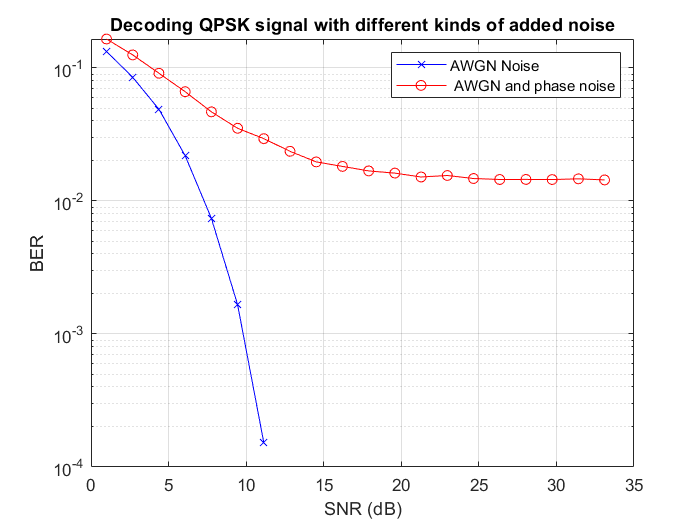

[~,AWGN_BER] = biterr(symbols,awgn_demod_symbol_sets,2);
[~,PHASE_AWGN_BER] = biterr(symbols,phase_awgn_demod_symbol_sets);

figure
semilogy(snr_values,AWGN_BER,"-bx");
title("Decoding QPSK signal with different kinds of added noise");
grid on ;
xlabel("SNR (dB)");
ylabel("BER");
hold on ;
semilogy(snr_values(1,1:20),PHASE_AWGN_BER(1:20,1),"ro-");
legend("AWGN Noise"," AWGN and phase noise");
hold off;

## Spectral Analysis

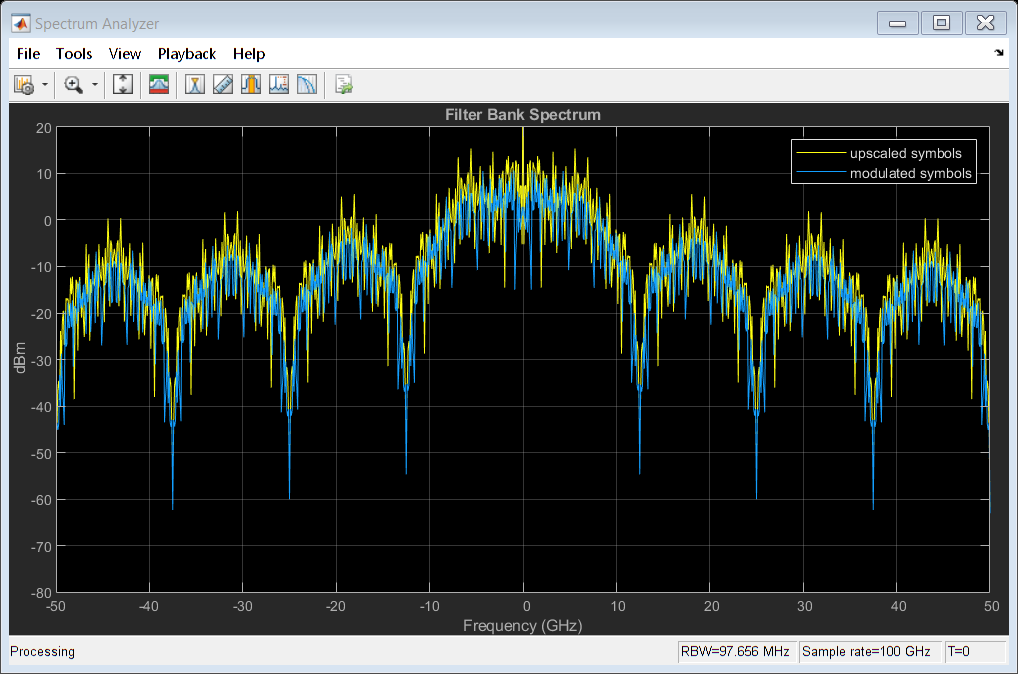

%symbol_num
%symbol_rate
%time_step

%%Change the symbols to be a known frequency
t = (0:symbol_num-1)/symbol_rate;
freq_inc = symbol_rate/symbol_num;
nyq_freq = symbol_rate/2;
y = zeros(sets_num,symbol_num);
amplitude = zeros(sets_num,symbol_num);
power = zeros(sets_num,symbol_num);


%%%%Creating an FFT using the Filter Bank Method
spectrum_scope = dsp.SpectrumAnalyzer( ...
    'NumInputPorts', 2, ...
    'ChannelNames', {'upscaled symbols','modulated symbols'}, ...
    'SampleRate',symbol_rate, ...
    'Method','Filter bank', ...
    'PlotAsTwoSidedSpectrum',true, ...
    'FrequencyResolutionMethod','NumFrequencyBands', ...
    'FFTLengthSource','Property', ...
    'FFTLength',1024, ...
    'SpectralAverages',1, ...
    'Title','Filter Bank Spectrum', ...
    'ShowLegend',true);

spectrum_scope(kron_symbols',mod_kron_symbols');

## **Plotting remnants**

%{
function no_out = plotting(variance, phase_noise, sets, modulated_symbols, symbols)

sets_num = length(sets);

figure
plot(cumsum(sqrt(variance).*phase_noise))
title('phase noise as random walk')

variances = (variance .* sets)';
phase_noise_sets = exp(1j*cumsum(sqrt(variances).*phase_noise));

phase_noise_only_modsym = modulated_symbols .* phase_noise_sets;
phase_noise_only_demodsym = pskdemod(phase_noise_only_modsym,4,0,"gray");

figure
for i=1:sets_num
    hold on
    scatter(real(phase_noise_only_modsym(i,:)),imag(phase_noise_only_modsym(i,:)));
end
title("Noisy Modulated Symbols passed through Channel")
xlabel("In-phase Amplitude")
ylabel("Quadrature Amplitude")
hold off

%{
figure
scatter(real(noisy_demod_symbols),imag(noisy_demod_symbols),"filled","d")
title("Demodulated Noisy Symbols 'passed' through Channel")
%}

figure
plot(phase_noise_only_demodsym,symbols,"rs")
title("Transmitted Symbols against Received Symbols")
xlabel("For perfect demodulation there should only be squares on (0,0),(1,1),(2,2),(3,3)")
plot(modulated_symbols)
axis([0,4,0,4])
grid on
no_out=phase_noise_only_demodsym(1,1);
end
%}